%%Aerodynamic Drag Force
rho=1.23%Air density

rho = 1.2300

Cd1=0.30%Drag Coeff. of Vehicle 1

Cd1 = 0.3000

Cd2=0.45%Drag Coeff. of Vehicle 2

Cd2 = 0.4500

Cd3=0.23%Drag Coeff. of Vehicle 3

Cd3 = 0.2300

%Cd=[0.30 0.45 0.23]
A=1.5%Cross Sec. area  of Vehicle 1

A = 1.5000

v=0:1:160%%Speed in (km/h)

v =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


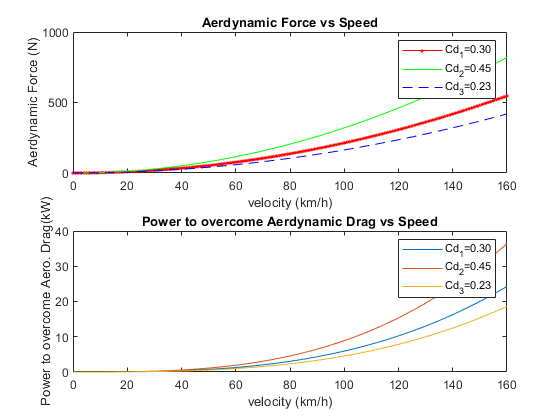

v1=v*1000/3600;% Speed coversion in m/sec
Fad1=0.5*rho*Cd1*A*(v1.*v1); %AeroDynam Force of Vehicle 1
Fad2=0.5*rho*Cd2*A*(v1.*v1); %AeroDynam Force of Vehicle 2
Fad3=0.5*rho*Cd3*A*(v1.*v1); %AeroDynam Force of Vehicle 3
subplot(2,1,1);
plot(v,Fad1,'.-r',v,Fad2,'-g',v,Fad3,'--b')
xlabel('velocity (km/h)');
ylabel('Aerdynamic Force (N)');
title('Aerdynamic Force vs Speed');
legend('Cd_1=0.30','Cd_2=0.45','Cd_3=0.23');
%%Power to overcome Aerodynamic Drag
Pad1=(Fad1.*v1)/1000;
Pad2=(Fad2.*v1)/1000;
Pad3=(Fad3.*v1)/1000;
subplot(2,1,2);
plot(v,Pad1,v,Pad2,v,Pad3)
xlabel('velocity (km/h)');
ylabel('Power to overcome Aero. Drag(kW)');
title('Power to overcome Aerdynamic Drag vs Speed');
legend('Cd_1=0.30','Cd_2=0.45','Cd_3=0.23');

fprintf('P_Aerodynamic(kW)=%1.2f at Velocity(km/h)=%5.2f\n',P_aerodynamic(1.2,0.3,1.5,60),60);

'P_aerodynamic' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Yogesh\Documents\MATLAB\Programes of James Larminie

Change the MATLAB current folder or add its folder to the MATLAB path.

fprintf('P_Aerodynamic(kW)=%1.2f at Velocity(km/h)=%5.2f\n',P_aerodynamic(1.2,0.3,1.5,160),160);
